t = load("t.txt");
x = transpose(load("x.txt")); % x(t) = A + B*t + C*sin(2*pi*t) + w(t)

Lineær modell / BLUE, 1b)

H = [ones(length(t), 1), t(:), sin(2*pi*t(:))];
H_T=transpose(H);

S=inv((H_T*H))*H_T*x;  % [A ; B ; C]
CRLB=diag(inv(H_T*H)); % [Var(A) ; Var(B) ; Var(C)]

x_est=transpose(S(1)+S(2)*t+S(3)*sin(2*pi*t));
x_true=transpose(1+2*t+3*sin(2*pi*t));

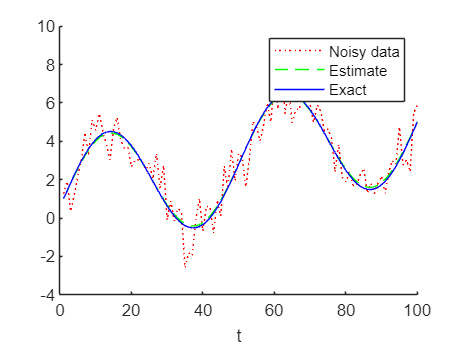

figure;
hold on;
plot(x,":","Color","r");
plot(x_est,"--","Color","g");
plot(x_true,"Color","b");
xlabel("t")
legend("Noisy data","Estimate","Exact");

Maximum likelihood, 2b)

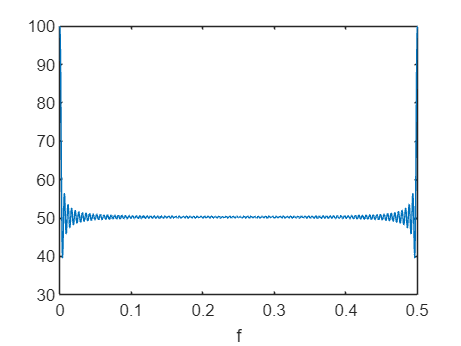

N=100;
n=0:N-1;
f=linspace(0,0.5,1000);
F=zeros(1,length(f));
for i = 1:length(f)
  F(i)=sum(cos(2*pi*f(i)*n).^2);
end

figure;
plot(f,F);
xlabel("f")

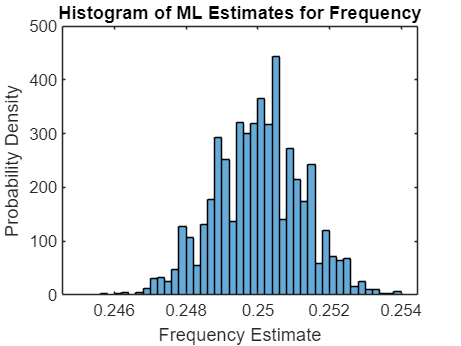

N = 10;         % Number of samples
f_true = 0.25;  % True frequency
sigma_2 = 0.01; % Variance of the noise
M = 5000;       % Number of realizations
delta_f = 0.0001; % Step size for frequency grid search

% Generate realizations and compute ML estimates
f_estimates = zeros(1, M);
for i = 1:M
    % Generate observed data
    n = 0:N-1;
    w = sqrt(sigma_2) * randn(1, N);
    x = cos(2*pi*f_true*n) + w;
    
    % Perform grid search
    likelihoods = zeros(1, round(0.5/delta_f));
    for j = 1:length(likelihoods)
        f = delta_f * j;
        likelihoods(j) = prod(1/sqrt(2*pi*sigma_2) * exp(-(x - cos(2*pi*f*n)).^2 / (2*sigma_2)));
    end
    
    % Find ML estimate
    [~, max_index] = max(likelihoods);
    f_estimates(i) = delta_f * max_index;
end

% Plot histogram of ML estimates
figure;
histogram(f_estimates, 'Normalization', 'pdf');
xlabel('Frequency Estimate');
ylabel('Probability Density');
title('Histogram of ML Estimates for Frequency');